%{
ES115- Class-Project Module 1 Project Bank
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-19

Purpose:
    - To model and analyze vehicle fuel consumption over a simplified driving cycle.
    - To relate fuel consumption rate to vehicle speed and acceleration.
    - To compute total fuel used and visualize how driving behavior affects efficiency.

Input:
    - Time vector from 0 to 100 seconds (t = 0:1:100)
    - Defined speed profile representing acceleration, cruising, deceleration, and توقف

Output:
    - Plot of speed vs time
    - Plot of fuel consumption rate vs time
    - Total fuel consumed over the driving cycle printed to command window

Engineering Algorithms:
    - Define time vector using fixed step size (1 s)
    - Construct piecewise speed function to simulate driving cycle
    - Compute acceleration using finite difference method (Δv/Δt)
    - Define fuel consumption model as a function of speed and acceleration
    - Evaluate fuel rate at each time step
    - Numerically integrate fuel rate using trapezoidal rule (trapz)
    - Plot speed vs time
    - Plot fuel consumption rate vs time
    - Compute and display total fuel consumption

MATLAB tools/functions:
    - vector operations
    - plot, xlabel, ylabel, title, grid
    - diff, trapz
    - fprintf
    - indexing and array slicing
    - figure
%}

 Project 19: Vehicle Fuel Consumption (Mechanical)

Objective: Estimate fuel usage over a driving cycle.

Core Tasks:

• Model vehicle speed over a simplified driving cycle.

• Relate fuel consumption rate to speed or acceleration.

• Compute total fuel consumed over the cycle.

Key Deliverables:

7

• MATLAB script computing fuel consumption.

• Speed vs. time and fuel usage plots.

• Interpretation of driving behavior on fuel efficiency.

clc; clear; close all;
% Simulation time vector (1 s resolution)
% Time vector
t = 0:1:100; % seconds
% Speed profile constructed piecewise: accel, cruise, decel, stop
% Speed profile (m/s)
v = zeros(size(t));
for i = 1:length(t)
    if t(i) <= 20
        v(i) = 0.5 * t(i); % acceleration
    elseif t(i) <= 60
        v(i) = 10; % constant speed
    elseif t(i) <= 80
        v(i) = 10 - 0.5*(t(i)-60); % deceleration
    else
        v(i) = 0; % stop
    end
end
% Compute acceleration via forward finite difference (initial zero)
% Acceleration (finite difference)
a = [0 diff(v)];
% Fuel model coefficients (units: L/s base, per m/s, per m/s^2)
% Fuel model constants
A = 0.0005;   % base consumption
B = 0.0002;   % speed factor
C = 0.0001;   % acceleration factor
% Instantaneous fuel rate combining speed and absolute accel effects
% Fuel consumption rate (L/s)
fuel_rate = A + B*v + C*abs(a);
% Integrate fuel rate over time to get total liters consumed
% Total fuel consumed
fuel_total = trapz(t, fuel_rate);
fprintf('Total Fuel Consumed: %.4f liters\n', fuel_total);

Total Fuel Consumed: 0.1720 liters


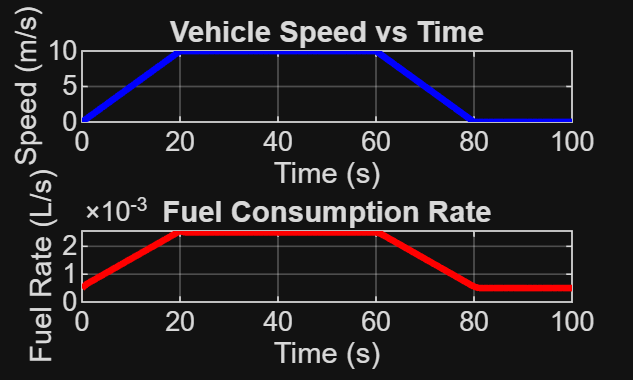

% Plot speed
figure;
subplot(2,1,1);%plots 2 axes but this is for the top one
plot(t, v, 'b', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Speed (m/s)');
title('Vehicle Speed vs Time');
grid on;
% Plot fuel rate
subplot(2,1,2);%gives 2 sets of axes this is for the bottom
plot(t, fuel_rate, 'r', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Fuel Rate (L/s)');
title('Fuel Consumption Rate');
grid on;